### 初始化参数

clc;clear;
fc = 3e3;           %中心频率为3kHz
fs = 144e3;
c = 1500;

### CW信号

T_CW =  0.005;
t_CW = 0:1/fs:T_CW-1/fs;
pulse_CW = cos(2*pi*fc*t_CW);
% N = length(pulse_CW);
% window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭

%pulse_CW = pulse_CW.* window;
N = length(pulse_CW);
CW = [pulse_CW zeros(1,4*N)];

#### 频谱

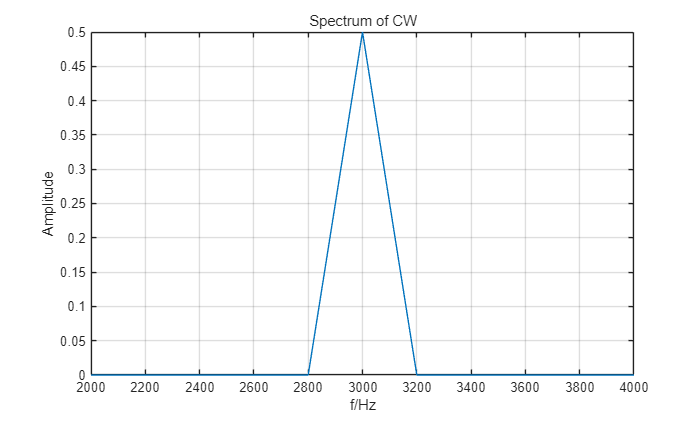

N_fft = length(pulse_CW);
CW_f = fftshift(fft(pulse_CW,N_fft))./N_fft;
freq = -fs/2:fs/N_fft:fs/2-fs/N_fft;


figure
plot(freq,abs(CW_f));
title('Spectrum of CW');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

#### 计算有效相关带宽和有效相关时宽

%计算有效相关时宽
Tc = cal_TSP(pulse_CW,fs);

% 计算有效相关带带宽
FSP = cal_FSP(CW_f,N_fft,fs);

fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 0.003333 s
计算有效相关带宽: 200.000000 Hz


保存为wav文件


filename = 'CW.wav';
audiowrite(filename, CW, fs);
Time = num2str(length(CW)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CW.wav 共0.025s


### M序列


T = 1;            %脉冲长度
t = 0:1/fs:T-1/fs;

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M_array = m_seq(gen_435, init_state);
M_array = M_array*2-1;   %0->-1
M_array = M_array(1:200);  %前200个

t1 = 0:1/fs:T/length(M_array)-1/fs;%每个符号的时间尺度
func = cos(2*pi*fc*t1);
N = length(func);
window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭
func = func.*window ;


pulse = [];
for i = 1:length(M_array)
    pulse = [ pulse M_array(i)*func];
end
M_seq = [pulse zeros(1,4*length(pulse))  ];


#### 频谱

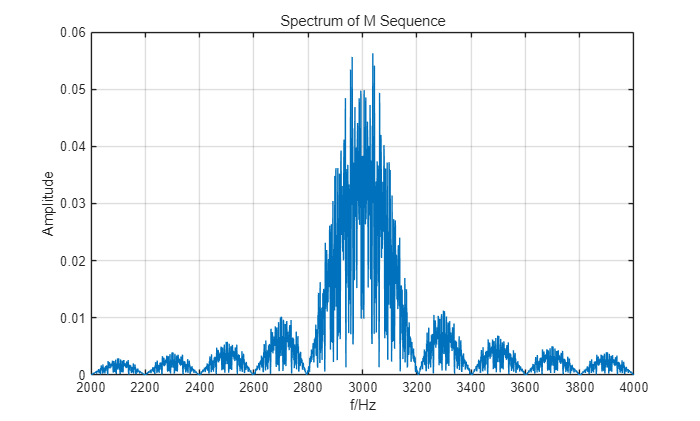

N_fft = length(pulse);
pulse_M_f = fftshift(fft(pulse,N_fft))./N_fft;
freq = (-fs/2:fs/N_fft:fs/2-fs/N_fft);

figure
plot(freq,abs(pulse_M_f));
title('Spectrum of M Sequence');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

#### 计算有效相关带宽和有效相关时宽

%计算有效相关时宽
Tc = cal_TSP(pulse,fs);

% 计算有效相关带带宽
FSP = cal_FSP(pulse_M_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 0.661463 s
计算有效相关带宽: 196.507632 Hz


#### 时频谱

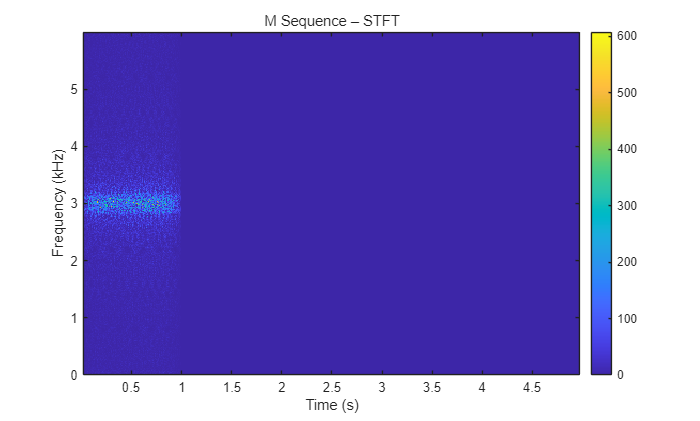

decim = 24;
res_M_seq  = M_seq (1:decim:end);

Nx   = numel(res_M_seq);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh


[tfr_M_seq,~,~] =tfrwv(res_M_seq.', t_idx, Nfft, 0);

fs_res = fs/decim; % 新采样率
tfr_M_seq_shifted = fftshift(tfr_M_seq, 1); % 沿频率轴(第1维)进行fftshift
f_vec_centered = (-Nfft/2:Nfft/2-1)/Nfft*fs_res; % 双边频率向量，以0为中心
t_sec = (t_idx - 1) / fs_res;
f_vec = (0:Nfft-1)/Nfft*fs_res;
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_M_seq_shifted));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('M Sequence – STFT');
colorbar;

保存为wav


filename = 'wav_files/M_seq.wav';
audiowrite(filename, M_seq, fs);
Time = num2str(length(M_seq)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：wav_files/M_seq.wav 共5s


#### 分集处理

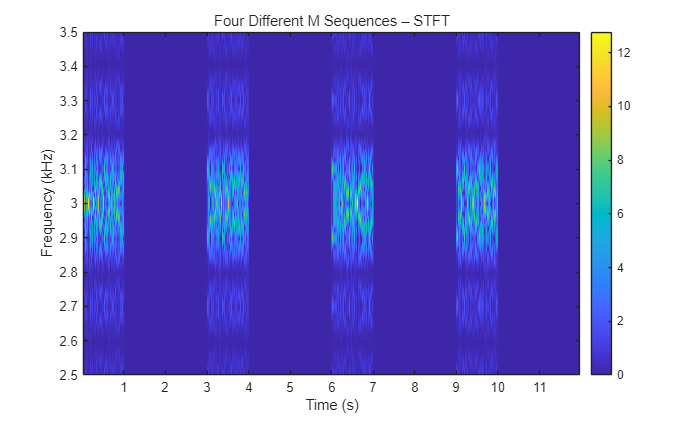

T = 1;            %脉冲长度
t = 0:1/fs:T-1/fs;

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M1 = m_seq(gen_435, init_state);

gen_453 = [1 0 0 1 0 1 0 1 1];
M2 = m_seq(gen_453, init_state);

gen_537 = [1 0 1 0 1 1 1 1 1];
M3 = m_seq(gen_537, init_state);

gen_543 = 	[1 0 1 1 0 0 0 1 1];
M4 = m_seq(gen_543, init_state);

M1 = M1*2-1;M2 = M2*2-1;M3 = M3*2-1;M4 = M4*2-1;
M1 = M1(1:200);M2 = M2(1:200);M3 = M3(1:200);M4 = M4(1:200);

t1 = 0:1/fs:T/length(M1)-1/fs;%每个符号的时间尺度
func = cos(2*pi*fc*t1);
N = length(func);
window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭
func = func.*window;

pulse_M1 = [];pulse_M2 = [];pulse_M3 = [];pulse_M4 = [];
for i = 1:length(M1)
    pulse_M1 = [ pulse_M1 M1(i)*func];
    pulse_M2 = [ pulse_M2 M2(i)*func];
    pulse_M3 = [ pulse_M3 M3(i)*func];
    pulse_M4 = [ pulse_M4 M4(i)*func];
end
pulse_M1 = [pulse_M1 zeros(1,2*length(pulse_M1))];%设置占空比
pulse_M2 = [pulse_M2 zeros(1,2*length(pulse_M2))];
pulse_M3 = [pulse_M3 zeros(1,2*length(pulse_M3))];
pulse_M4 = [pulse_M4 zeros(1,2*length(pulse_M4))];
pulse_M = [pulse_M1 pulse_M2 pulse_M3 pulse_M4];


decim   = 24;           % <= 24 才安全
fs_res  = fs/decim;     % 新采样率 ≥ 6 kHz
res_pulse_M    = pulse_M   (1:decim:end);

%% 2. STFT（以 tfrstft 为例）
Nx   = numel(res_pulse_M);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh
[tfr_multiM,~,~] = tfrstft(res_pulse_M.', t_idx, Nfft, win);

% 真实频率向量（Hz）：
f_vec = (0:Nfft-1)/Nfft*fs_res;

% 真实时间向量（s）：
%t_sec = -t_i/fs_res;
t_sec = (t_idx - 1) / fs_res;    % ← 自己算，而不是用 t_i
%% 3. 画图
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_multiM));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
ylim([2.5,3.5]);
title('Four Different M Sequences – STFT');
colorbar;

filename = 'wav_files/CDMA_M.wav';
audiowrite(filename, pulse_M, fs);
Time = num2str(length(pulse_M)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CDMA_M.wav 共12s


### Costas序列

T = 1.4;            %脉冲长度
t = 0:1/fs:T-1/fs;

Costas_array = [2 8 9 12 4 14 10 15 13 7 6 3 11 1 5];%15个符号
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);

N = length(t1);
window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭

pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1).*window ];
end

#### 频谱

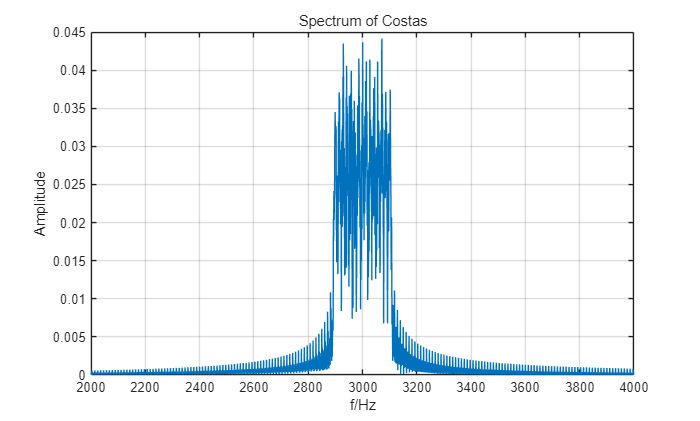

N_fft = length(pulse_costas);
pulse_costas_f = fftshift(fft(pulse_costas,N_fft))./N_fft;
freq = (-fs/2:fs/N_fft:fs/2-fs/N_fft);

figure
plot(freq,abs(pulse_costas_f));
title('Spectrum of Costas');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

计算有效相关带宽和有效相关时宽


%计算有效相关时宽
Tc = cal_TSP(pulse_costas,fs);

% 计算有效相关带带宽
FSP = cal_FSP(pulse_costas_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 0.926090 s
计算有效相关带宽: 173.958058 Hz


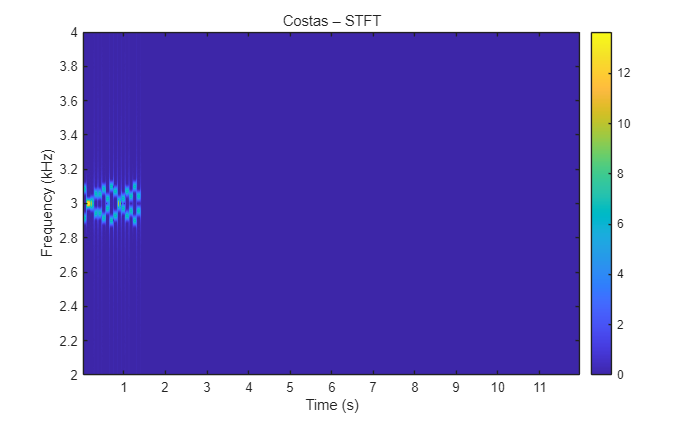


Costas = [pulse_costas zeros(1,4*length(pulse_costas))];
res_Costas = Costas(1:decim:end);

[tfr_Costas,~,~] = tfrstft(res_Costas.', t_idx, Nfft, win);
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_Costas));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
ylim([2,4]);
title('Costas – STFT');
colorbar;

保存为wav

filename = 'wav_files/Costas.wav';
audiowrite(filename, Costas, fs);
Time = num2str(length(Costas)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：Costas.wav 共7s


#### 分集处理

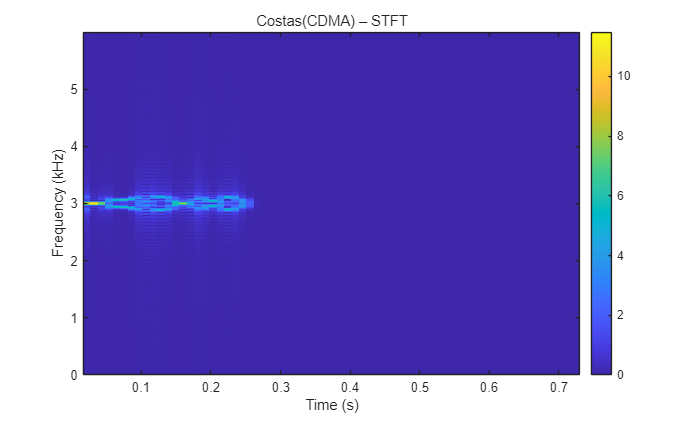

T = 0.25;            %脉冲长度
t = 0:1/fs:T-1/fs;
Costas_array = [2 8 9 12 4 14 10 15 13 7 6 3 11 1 5];%15个符号
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);

N = length(t1);
window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭

pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1).*window ];

end
Multi_Costas = [pulse_costas zeros(1,2*length(pulse_costas))];



decim   = 24;           % <= 24 才安全
fs_res  = fs/decim;     % 新采样率 ≥ 6 kHz

res_Multi_Costas    = Multi_Costas   (1:decim:end);

%% 2. STFT（以 tfrstft 为例）
Nx   = numel(res_Multi_Costas);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh
[tfr_res_Multi_Costas,f_idx,~] = tfrstft(res_Multi_Costas.', t_idx, Nfft, win);

% 真实频率向量（Hz）：
f_vec = (0:Nfft-1)/Nfft*fs_res;

% 真实时间向量（s）：
%t_sec = -t_i/fs_res;
t_sec = (t_idx - 1) / fs_res;    % ← 自己算，而不是用 t_i
%% 3. 画图
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_res_Multi_Costas));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Costas(CDMA) – STFT');
colorbar;

保存wav

filename = 'wav_files/CDMA_Costas.wav';
audiowrite(filename, Multi_Costas, fs);
Time = num2str(length(Multi_Costas)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CDMA_Costas.wav 共5s


### HFM信号

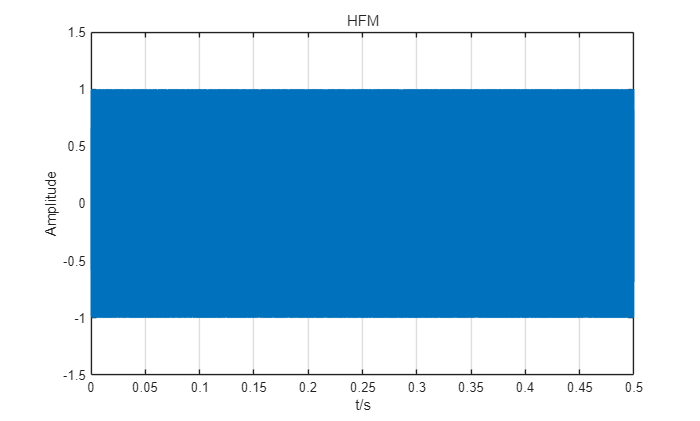

T_HFM =  3;%带宽为200Hz

t_hfm = 0.5/fs : 1/fs : T_HFM-0.5/fs;
f0 = 2500;
pulse_HFM = cos(2*pi*(f0*t_hfm+200*log(t_hfm)));  %调频参数K=1
% N = length(t_hfm);
% window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭
% pulse_HFM = pulse_HFM.*window;

HFM = [pulse_HFM zeros(1,4*length(pulse_HFM))];

figure
plot(t_hfm,pulse_HFM);
axis([0,0.5,-1.5,1.5]);grid on;
title('HFM');
xlabel('t/s');ylabel('Amplitude');

#### 频谱

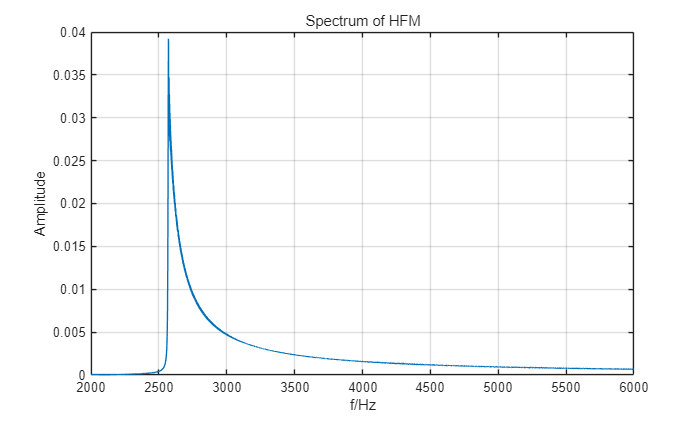

N_fft = length(pulse_HFM);
pulse_HFM_f = fftshift(fft(pulse_HFM,N_fft))./N_fft;
freq = (-fs/2:fs/N_fft:fs/2-fs/N_fft);

figure
plot(freq,abs(pulse_HFM_f));
title('Spectrum of HFM');
xlim([2000,6000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

#### 计算有效相关带宽和时宽


%计算有效相关时宽
Tc = cal_TSP(pulse_HFM,fs);

% 计算有效相关带带宽
FSP = cal_FSP(pulse_HFM_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 2.000156 s
计算有效相关带宽: 202.024224 Hz


#### 时频分析

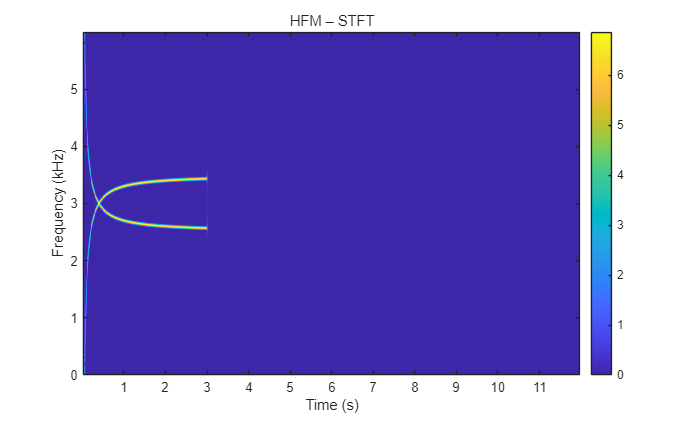

res_HFM    = HFM   (1:decim:end);
[tfr_HFM,~,~] = tfrstft(res_HFM.', t_idx, Nfft, win);
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_HFM));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');

title('HFM – STFT');
colorbar;

保存为wav

filename = 'wav_files/HFM.wav';
audiowrite(filename, HFM, fs);
Time = num2str(length(HFM)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：HFM.wav 共15s


#### 分集处理

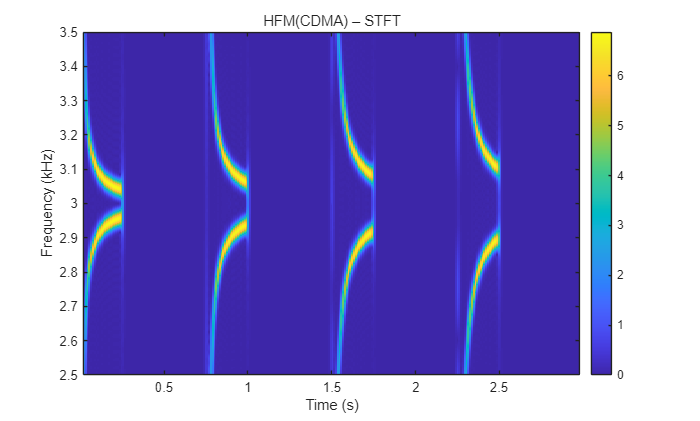


t_hfm = 0.5/fs : 1/fs : T-0.5/fs;
k1 = 10;
k2 = 15;
k3 = 20;
k4 = 25;
pulse1 = cos(2*pi*(fc*t_hfm+k1*log(t_hfm)));  %调频参数K=1
pulse2 = cos(2*pi*(fc*t_hfm+k2*log(t_hfm)));  %调频参数K=2
pulse3 = cos(2*pi*(fc*t_hfm+k3*log(t_hfm)));  %调频参数K=3
pulse4 = cos(2*pi*(fc*t_hfm+k4*log(t_hfm)));  %调频参数K=4

pulse1 = [pulse1 zeros(1,2*length(pulse1))];
pulse2 = [pulse2 zeros(1,2*length(pulse2))];
pulse3 = [pulse3 zeros(1,2*length(pulse3))];
pulse4 = [pulse4 zeros(1,2*length(pulse4))];

Multi_HFM = [pulse1 pulse2 pulse3 pulse4];


decim   = 24;           % <= 24 才安全
fs_res  = fs/decim;     % 新采样率 ≥ 6 kHz


res_Multi_HFM    = Multi_HFM   (1:decim:end);

%% 2. STFT（以 tfrstft 为例）
Nx   = numel(res_Multi_HFM);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh
[tfr_res_Multi_HFM,f_idx,~] = tfrstft(res_Multi_HFM.', t_idx, Nfft, win);

% 真实频率向量（Hz）：
f_vec = (0:Nfft-1)/Nfft*fs_res;

% 真实时间向量（s）：
%t_sec = -t_i/fs_res;
t_sec = (t_idx - 1) / fs_res;    % ← 自己算，而不是用 t_i
%% 3. 画图
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_res_Multi_HFM));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
ylim([2.5,3.5]);
title('HFM(CDMA) – STFT');
colorbar;

filename = 'wav_files/CDMA_HFM.wav';
audiowrite(filename, Multi_HFM, fs);
Time = num2str(length(Multi_HFM)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CDMA_HFM.wav 共1.25s


### 模糊函数分析

#### CW信号

fs = 6e3;
T = 6;            %脉冲长度6s
num_pulse = 1;     %脉冲个数500
t = 0:1/fs:T-1/fs;
pulse_CW = cos(2*pi*fc*t);


[RDM, vel_axis, range_axis] = range_doppler(pulse_CW, pulse_CW,fs, 1500, 20);

    
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, log10(RDM));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Ambiguity of CW');
colorbar;


#### M序列

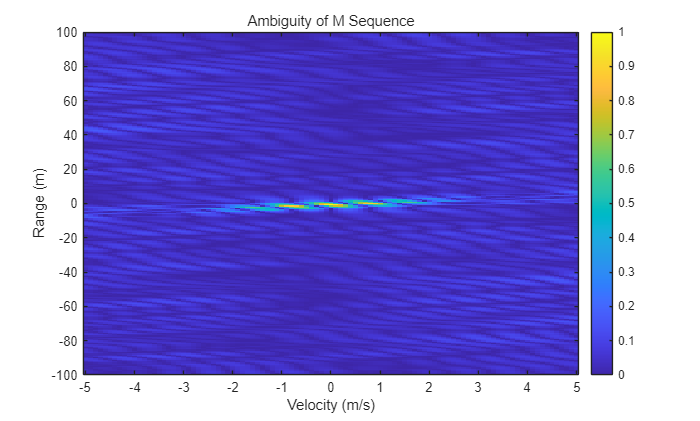

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M1 = m_seq(gen_435, init_state);

gen_453 = [1 0 0 1 0 1 0 1 1];
M2 = m_seq(gen_453, init_state);

M1 = 2*M1-1;M2 = 2*M2-1;
M1 = M1(1:200);M2 = M2(1:200);

T=0.635;
fs = 1000;
t1 = 0:1/fs:T/length(M1)-1/fs;%每个符号的时间尺度

fc = 500;
func = cos(2*pi*fc*t1);

pulse_M1 = [];pulse_M2 = [];
for i = 1:length(M1)
    pulse_M1 = [ pulse_M1 M1(i)*func];
    pulse_M2 = [ pulse_M2 M2(i)*func];
end


c=1500;
vel_resolution = 0.01;
max_velocity = 5;


[Waf, vel_axis,range_axis] = wideband_ambiguity(pulse_M1, pulse_M1, fs, c, max_velocity);
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, Waf./max(max(Waf)));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Ambiguity of M Sequence');
ylim([-100,100]);
colorbar;

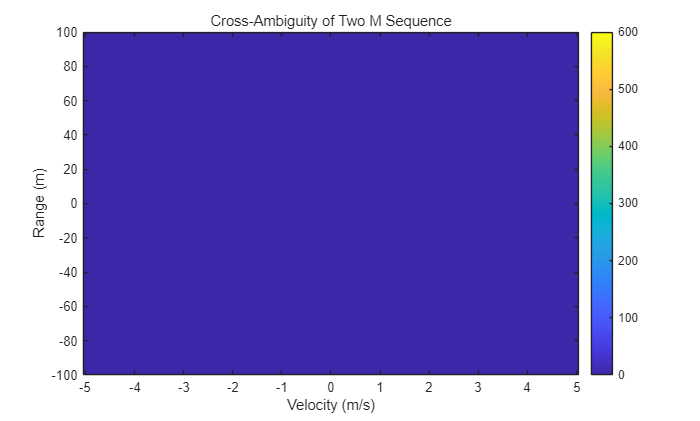


% 获取第一张图的 Waf 的最大值和最小值
cmin = min(Waf(:));
cmax = max(Waf(:));

[Waf, vel_axis,range_axis] = wideband_ambiguity(pulse_M1, pulse_M2, fs, c, max_velocity);
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, Waf./(max(max(Waf))+eps));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Cross-Ambiguity of Two M Sequence');
ylim([-100,100]);
colorbar;
% 设置第二张图的 colorbar 范围与第一张图一致
clim([cmin, cmax]);

#### Costas序列

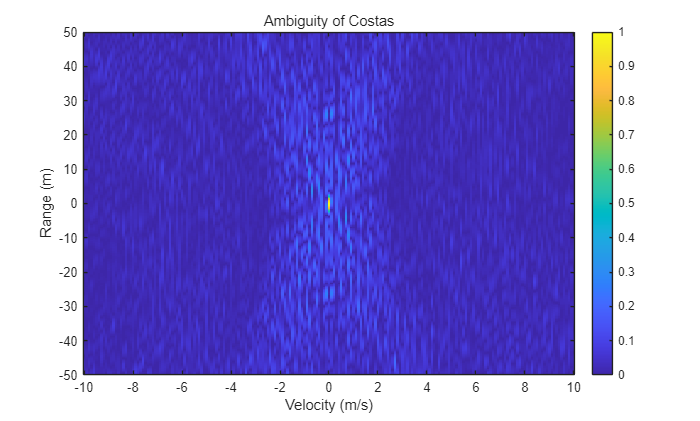

Costas_array = [2 8 9 12 4 14 10 15 13 7 6 3 11 1 5];%15个符号

T = 1.4;            %脉冲长度
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);

pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1) ];

end


[RDM, vel_axis, range_axis] = wideband_ambiguity(pulse_costas, pulse_costas, fs, c, max_velocity);
    
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, RDM./max(max(RDM)));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
ylim([-50,50]);
title('Ambiguity of Costas');
colorbar;

#### HFM信号

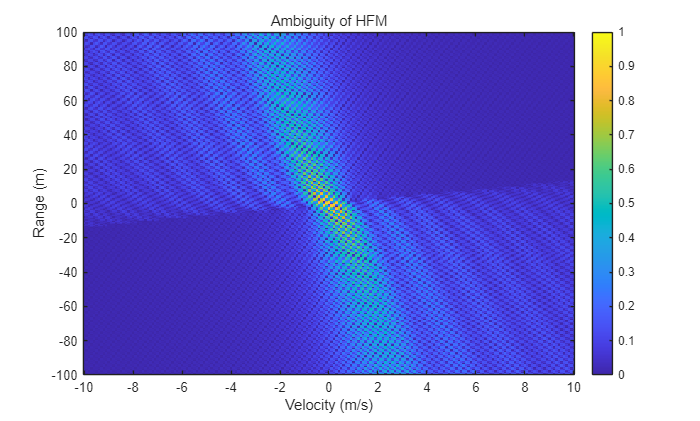

fs = 6e3;
t_hfm = 0.5/fs : 1/fs : T-0.5/fs;
pulse_HFM = cos(2*pi*(fc*t_hfm+10*log(t_hfm)));  %调频参数K=10

max_velocity = 10;
[RDM, vel_axis, range_axis] = wideband_ambiguity(pulse_HFM, pulse_HFM, fs, c, max_velocity);
    
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, RDM./max(max(RDM)));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
ylim([-100,100]);
title('Ambiguity of HFM');
colorbar;